clear, clc

function [a] = A(J)
a = J.*(J+1);
end

function [b] = B(J,M) %j-2 to j
b = (1./((2.*J)-1)).*sqrt(((J+abs(M)).*(J+abs(M)-1).*(J-abs(M)).*(J-abs(M)-1))./(((2.*J)+1).*((2.*J)-3)));
end

function [c] = C(J,M) % j to j
c =((1/3)+(2/3).*(J.*(J+1)-3.*M.^2)./(((2.*J)-1).*((2.*J)+3)));
end

function [d] = D(J,M) % j+2 to j
d = (1./((2.*J)+3)).*sqrt( ((J+abs(M)+2).*(J+abs(M)+1).*(J-abs(M)+2).*(J-abs(M)+1))./(((2.*J)+5).*((2.*J)+1)));
end

J_num = [0:2:10]

J_num =      0     2     4     6     8    10


M_num = [0:1:10]

M_num =      0     1     2     3     4     5     6     7     8     9    10


linearly = zeros(J_num(end)+1,M_num(end)+1,20001);

M_idx = 9

M_idx = 9

Jmax = 200;
M = M_idx;
J = (0:Jmax)*2

J =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


g = length(J);
r = [0:0.1:200]';
l = length(r);

for s=1:l

I = r(s,1)*0.01;% 1*I = 10^10 W/cm^2
dw = I*((10.6*2.73e9^2)/(4*2.17e-24))*1e-40; %dw = dalpha*field^2/4B
wp = I*(6.2e-40*2.73e9^2)/(4*2.17e-24);
wpara = I*(16.8e-40*2.73e9^2)/(4*2.17e-24);

F1 = D(J,M);% j+2 to j
f1 = D(J,M).*-dw;
f2 = C(J,M).*-dw-wp+A(J);
f3 = B(J,M).*-dw;
v1 = diag(f1,1);
v2 = diag(f2,0);
v3 = diag(f3,-1);
l = length(v1);
v1(:,l) = []; v1(l,:) = [];
v3(:,1) = []; v3(1,:) = [];
T = v1+v2+v3;
[V,lambda] = eig(T);

F2 = C(J,M);% j to j
F3 = B(J,M);%j-2 to j
V1 = diag(F1,0) ;
V2 = diag(F2,0) ;
V3 = diag(F3,0);

for n = 1:g
c = V(:,n);
B1 = (V3*c)'; c1 = c;
B1(:,1) = [];
c1(l-1,:) = [];
expecB = B1*c1;
expecC = (V2*c)'*c;
D1 = (V1*c)'; c2 = c;
c2(1,:) = [];
D1(:,l-1) = [];
expecD = D1*c2;
E(:,n) = expecB+expecD+expecC;
end

E(1:1);
k(s,1:6) = E(1,1:6);
end

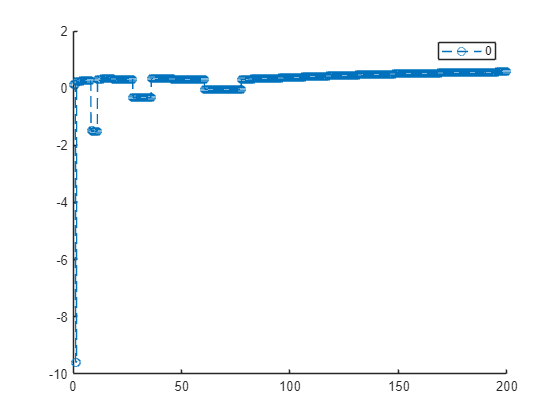

data = [r k];
figure;
hold on
plot(r,k(:,6),'--o')
hold off
% ylim([0, 1])
xlim([0 200])
legend('0','2','4','6','8','10')

% for idx = 1:numel(J_num)
%     linearly(J_num(idx)+1,M+1,:) = k(:,idx);
% end